# **Chapter 19 Mini Quiz (Q1)**

Function

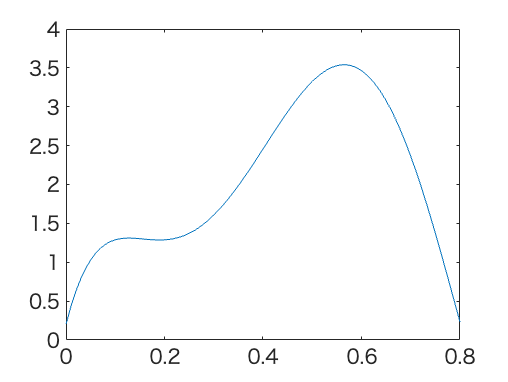

f=@(x) 400.*x.^5 - 900.*x.^4 + 675.*x.^3 - 200.*x.^2 + 25.*x + 0.2;

xx = 0 : 0.01 : 0.8;
yy = f(xx);

plot(xx, yy, '-')

To integrate function from 0 to 0.8 *(doing analytical integration)*

format short
a = 0;
b = 0.8;
p = [400 -900 675 -200 25 0.2];
q = polyint(p); % integrate polynomial equation (gives us the EXACT integration)
Itrue = diff(polyval(q, [a, b])) % for relative value

Itrue = 1.6405

Plot original function along with trapezoidal rule ns = 1 (single application)

ns = 1

ns = 1


% NEW
I_trap_ns1 = trap(f, a, b, ns)

I_trap_ns1 = 0.1728

err_ns1 = ((Itrue - I_trap_ns1) / Itrue) * 100

err_ns1 = 89.4668

Plot original function along with trapezoidal rule ns = 4

ns = 4

ns = 4


% NEW
I_trap_ns4 = trap(f, a, b, ns)

I_trap_ns4 = 1.4848

err_ns4 = ((Itrue - I_trap_ns4) / Itrue) * 100

err_ns4 = 9.4928

Single application of Simpson’s 1/3 rule (ns = 1)

y = f(x);

% NEW
h = (b - a) / 2

h = 0.4000

I_simpson13_ns1 = (h/3) * (y(1) + 4*y(2) + y(3)) % formula from the slides (page 18)

I_simpson13_ns1 = 1.1863

err_simpson13_ns1 = ((Itrue - I_simpson13_ns1) / Itrue) * 100

err_simpson13_ns1 = 27.6902

# **TODO: FINISH CODE BELOW**

Composite Simpson’s 1/3 rule for 4 segments (ns = 4)

ns = 4

ns = 4


for i = 1:ns
    % compute area for each segment
    h = (b - a) / (2*ns)
    simpson13_ns4(i) = (h)
end

h = 0.1000

simpson13_ns4 = 0.1000

h = 0.1000

simpson13_ns4 =     0.1000    0.1000


h = 0.1000

simpson13_ns4 =     0.1000    0.1000    0.1000


h = 0.1000

simpson13_ns4 =     0.1000    0.1000    0.1000    0.1000



% calculate total area

Single application of Simpson’s 3/8 rule (ns = 1)

ns = 1

ns = 1

y = f(x);

% NEW
h = (b - a) / 3

h = 0.2667

I_simpson38_ns1 = (3*h/8) * (y(1) + 3*y(2) + 3*y(3) + 3*y(4)) % formula from the slides (page 18)

I_simpson38_ns1 = 2.2913

err_simpson38_ns1 = ((Itrue - I_simpson38_ns1) / Itrue) * 100

err_simpson38_ns1 = -39.6680

Composite Simpson’s 3/8 rule for 4 segments (ns = 4)

ns = 4

ns = 4

for i = 1:ns
    % compute area for each segment
    % h = (b - a) / (2*ns)
    % simpson
end